## AOMIC PIOP1 Replication Sample - Whole-Brain Coupling Plot Across Conditions 

Computation of coupling measure-specific brain-average coupling values for all six conditions, taking the mean across the four measure-specific brain-average coupling values per condition and creating the violin plot visualizing condition-specific differences in brain-average SC-FC coupling. Run ANOVA to test for significant differences between brain-average condition-specific SC-FC coupling.

Before running this script: 

- run all scripts in AOMIC Data Prep 

**1. Compute brain-average coupling values **

1.1. Resting-state 

for i = 1:126
    whole_brain_values_AOMIC_PIOP1_rest{i,1} = mean(final_r_all_AOMIC_PIOP1_rest_126{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP1_rest{i,2} = mean(final_r_all_AOMIC_PIOP1_rest_126{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP1_rest{i,3} = mean(final_r_all_AOMIC_PIOP1_rest_126{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP1_rest{i,4} = mean(final_r_all_AOMIC_PIOP1_rest_126{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP1_rest_table = cell2table(whole_brain_values_AOMIC_PIOP1_rest);
 whole_brain_values_AOMIC_PIOP1_rest_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP1_rest_table = 126×4 table
      Pl          G         Cos         SI   
    _______    _______    _______    ________

    0.15524    0.18762    0.19119     0.10006
    0.18329    0.19622    0.21093     0.15839
    0.16896    0.18045    0.18491      0.1415
     0.1816    0.19653    0.20223     0.16437
    0.17209    0.18853    0.19598     0.16306
    0.14889    0.16609    0.16575     0.12182
    0.18225    0.19217    0.19615     0.15667
    0.13544    0.15965    0.14996    0.092428
     0.1916    0.19919    0.21027      0.1751
    0.15506    0.15945    0.15978     0.11256
    0.18763    0.19177    0.20087     0.14009
    0.23858    0.22074    0.25011     0.23955
    0.16688    0.17532    0.17435     0.13677
    0.15612    0.17346     0.1731     0.11762
    0.14541    0.16984    0.16619     0.10298
    0.18344    0.18159   

1.2. Working memory

for i = 1:126
    whole_brain_values_AOMIC_PIOP1_wm{i,1} = mean(final_r_all_AOMIC_PIOP1_wm_126{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP1_wm{i,2} = mean(final_r_all_AOMIC_PIOP1_wm_126{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP1_wm{i,3} = mean(final_r_all_AOMIC_PIOP1_wm_126{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP1_wm{i,4} = mean(final_r_all_AOMIC_PIOP1_wm_126{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP1_wm_table = cell2table(whole_brain_values_AOMIC_PIOP1_wm);
 whole_brain_values_AOMIC_PIOP1_wm_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP1_wm_table = 126×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.22647    0.26598    0.27468    0.17794
    0.22492    0.24844     0.2546    0.19878
    0.20101    0.22982    0.22257    0.16106
     0.2365    0.24162    0.24748     0.2212
    0.24396     0.2568     0.2578    0.24257
    0.21787    0.24632    0.25564    0.20369
    0.25847     0.2811    0.29852    0.24651
    0.20764    0.23825    0.23631    0.14667
    0.22145    0.24394    0.24791      0.216
    0.21739    0.23331     0.2356    0.13865
     0.2643    0.27869    0.29758    0.23759
    0.22595     0.2421    0.24681    0.19598
    0.23973    0.24595    0.24565    0.20594
    0.23471    0.25908    0.26559    0.17991
     0.2127    0.26028    0.26309    0.15811
    0.24757    0.24504    0.24413    0.19914

1.3. Emotion anticipation

for i = 1:126
    whole_brain_values_AOMIC_PIOP1_emo_anti{i,1} = mean(final_r_all_AOMIC_PIOP1_emo_anti_126{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP1_emo_anti{i,2} = mean(final_r_all_AOMIC_PIOP1_emo_anti_126{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP1_emo_anti{i,3} = mean(final_r_all_AOMIC_PIOP1_emo_anti_126{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP1_emo_anti{i,4} = mean(final_r_all_AOMIC_PIOP1_emo_anti_126{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP1_emo_anti_table = cell2table(whole_brain_values_AOMIC_PIOP1_emo_anti);
 whole_brain_values_AOMIC_PIOP1_emo_anti_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP1_emo_anti_table = 126×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

     0.2354    0.27376     0.2785     0.1837
    0.23354    0.25716    0.26735    0.22646
    0.24193    0.25428    0.25999    0.21827
    0.25664    0.25054    0.25997    0.25009
    0.26153    0.28278    0.28579    0.27837
    0.21617    0.25751    0.26004    0.19922
    0.24166    0.26947    0.27914     0.2494
    0.20453     0.2279    0.22745    0.14394
    0.25345      0.274    0.29384    0.25543
    0.24725    0.25245     0.2599    0.17864
    0.28195    0.28969      0.303    0.25091
    0.24558    0.26414    0.27359    0.21073
     0.2548    0.26078    0.26423    0.22188
    0.29386    0.29756     0.3178    0.25718
    0.24124    0.27669    0.28566    0.18123
    0.26906    0.25528    0.26493    0

1.4. Emotion matching 

for i = 1:126
    whole_brain_values_AOMIC_PIOP1_emo_match{i,1} = mean(final_r_all_AOMIC_PIOP1_emo_match_126{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP1_emo_match{i,2} = mean(final_r_all_AOMIC_PIOP1_emo_match_126{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP1_emo_match{i,3} = mean(final_r_all_AOMIC_PIOP1_emo_match_126{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP1_emo_match{i,4} = mean(final_r_all_AOMIC_PIOP1_emo_match_126{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP1_emo_match_table = cell2table(whole_brain_values_AOMIC_PIOP1_emo_match);
 whole_brain_values_AOMIC_PIOP1_emo_match_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP1_emo_match_table = 126×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.19544     0.2301    0.23142    0.13777
    0.18957    0.22022    0.22366     0.1616
    0.21882    0.22747     0.2311    0.19391
    0.22795    0.23716     0.2463    0.20913
    0.26798    0.27573    0.28791    0.29326
     0.1995     0.2331    0.23732    0.17985
    0.21166    0.24699    0.24892    0.19699
    0.19569    0.21451    0.21722    0.15261
    0.20385    0.23557    0.23947    0.17146
    0.22573     0.2323    0.23441    0.15548
    0.25481    0.26453    0.27954    0.21975
    0.18435    0.20992    0.21065    0.16889
    0.18961    0.21588    0.21467    0.15204
    0.19867    0.23008     0.2324    0.16438
    0.17897    0.22793    0.22204    0.12248
    0.21586    0.21556    0.21923    

1.5. Face perception

for i = 1:126
    whole_brain_values_AOMIC_PIOP1_face{i,1} = mean(final_r_all_AOMIC_PIOP1_face_126{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP1_face{i,2} = mean(final_r_all_AOMIC_PIOP1_face_126{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP1_face{i,3} = mean(final_r_all_AOMIC_PIOP1_face_126{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP1_face{i,4} = mean(final_r_all_AOMIC_PIOP1_face_126{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP1_face_table = cell2table(whole_brain_values_AOMIC_PIOP1_face);
 whole_brain_values_AOMIC_PIOP1_face_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP1_face_table = 126×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.13852    0.17694    0.17629    0.10132
    0.18791    0.20549    0.21584    0.16935
    0.19124     0.2013    0.20296    0.15657
     0.1935    0.20015    0.20131    0.18466
    0.19355    0.21442    0.21838    0.16068
    0.17296    0.20709    0.21964    0.16523
    0.23297    0.23625    0.24691    0.23515
     0.1731    0.18252    0.18988    0.10707
    0.19701    0.21183    0.22346    0.19009
    0.15342     0.1643    0.16253    0.10352
    0.22092     0.2146    0.22186    0.19621
    0.19327    0.21199     0.2228    0.16197
    0.19437    0.19398    0.19765    0.17158
    0.23117     0.2452    0.26597    0.19024
    0.15459    0.17971    0.19153    0.11829
     0.1764    0.17849    0.18065    0.164

1.6. Gender stroop

for i = 1:126
    whole_brain_values_AOMIC_PIOP1_gender{i,1} = mean(final_r_all_AOMIC_PIOP1_gender_126{i,2}(:,1));% Pl
    whole_brain_values_AOMIC_PIOP1_gender{i,2} = mean(final_r_all_AOMIC_PIOP1_gender_126{i,2}(:,2));% G 
    whole_brain_values_AOMIC_PIOP1_gender{i,3} = mean(final_r_all_AOMIC_PIOP1_gender_126{i,2}(:,3));% Cos
    whole_brain_values_AOMIC_PIOP1_gender{i,4} = mean(final_r_all_AOMIC_PIOP1_gender_126{i,2}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_AOMIC_PIOP1_gender_table = cell2table(whole_brain_values_AOMIC_PIOP1_gender);
 whole_brain_values_AOMIC_PIOP1_gender_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_AOMIC_PIOP1_gender_table = 126×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

     0.2327    0.26595     0.2692    0.18498
    0.25731    0.27543    0.29302    0.25123
    0.25347    0.27252    0.27652    0.21499
     0.2447    0.24704    0.25959    0.22753
    0.30615    0.31327    0.32593    0.29537
    0.20969     0.2555    0.26111    0.18595
    0.25598    0.28781    0.29436    0.22863
    0.24889    0.26001    0.26239    0.17545
    0.26605    0.27937    0.29744    0.28012
    0.26393    0.26322     0.2723    0.20076
    0.27759    0.28958    0.30303    0.24439
    0.27566    0.27505    0.29615    0.27342
    0.26184    0.25844    0.26133    0.24015
    0.27009    0.28399    0.29943    0.24158
    0.22989    0.25765    0.26481    0.17366
    0.27152    0.25863    0.26965    0.2

**2. Average coupling measures within the conditions **

2.1. Take average across all resting-state values 

Rest_values_from_all_measures = [whole_brain_values_AOMIC_PIOP1_rest_table.Pl whole_brain_values_AOMIC_PIOP1_rest_table.G whole_brain_values_AOMIC_PIOP1_rest_table.Cos whole_brain_values_AOMIC_PIOP1_rest_table.SI]

Rest_values_from_all_measures =     0.1552    0.1876    0.1912    0.1001
    0.1833    0.1962    0.2109    0.1584
    0.1690    0.1804    0.1849    0.1415
    0.1816    0.1965    0.2022    0.1644
    0.1721    0.1885    0.1960    0.1631
    0.1489    0.1661    0.1658    0.1218
    0.1823    0.1922    0.1962    0.1567
    0.1354    0.1597    0.1500    0.0924
    0.1916    0.1992    0.2103    0.1751
    0.1551    0.1594    0.1598    0.1126


Rest_all = mean(Rest_values_from_all_measures,2)

Rest_all =     0.1585
    0.1872
    0.1690
    0.1862
    0.1799
    0.1506
    0.1818
    0.1344
    0.1940
    0.1467


2.2. Take average across all working memory values

Wm_values_from_all_measures = [whole_brain_values_AOMIC_PIOP1_wm_table.Pl whole_brain_values_AOMIC_PIOP1_wm_table.G whole_brain_values_AOMIC_PIOP1_wm_table.Cos whole_brain_values_AOMIC_PIOP1_wm_table.SI]

Wm_values_from_all_measures =     0.2265    0.2660    0.2747    0.1779
    0.2249    0.2484    0.2546    0.1988
    0.2010    0.2298    0.2226    0.1611
    0.2365    0.2416    0.2475    0.2212
    0.2440    0.2568    0.2578    0.2426
    0.2179    0.2463    0.2556    0.2037
    0.2585    0.2811    0.2985    0.2465
    0.2076    0.2382    0.2363    0.1467
    0.2214    0.2439    0.2479    0.2160
    0.2174    0.2333    0.2356    0.1387


Wm_all = mean(Wm_values_from_all_measures,2)

Wm_all =     0.2363
    0.2317
    0.2036
    0.2367
    0.2503
    0.2309
    0.2711
    0.2072
    0.2323
    0.2062


2.3. Take average across all emotion anticipation values 

Emo_anti_values_from_all_measures = [whole_brain_values_AOMIC_PIOP1_emo_anti_table.Pl whole_brain_values_AOMIC_PIOP1_emo_anti_table.G whole_brain_values_AOMIC_PIOP1_emo_anti_table.Cos whole_brain_values_AOMIC_PIOP1_emo_anti_table.SI]

Emo_anti_values_from_all_measures =     0.2354    0.2738    0.2785    0.1837
    0.2335    0.2572    0.2673    0.2265
    0.2419    0.2543    0.2600    0.2183
    0.2566    0.2505    0.2600    0.2501
    0.2615    0.2828    0.2858    0.2784
    0.2162    0.2575    0.2600    0.1992
    0.2417    0.2695    0.2791    0.2494
    0.2045    0.2279    0.2275    0.1439
    0.2535    0.2740    0.2938    0.2554
    0.2473    0.2525    0.2599    0.1786


Emo_anti_all = mean(Emo_anti_values_from_all_measures,2)

Emo_anti_all =     0.2428
    0.2461
    0.2436
    0.2543
    0.2771
    0.2332
    0.2599
    0.2010
    0.2692
    0.2346


2.4. Take average across all emotion matching values 

Emo_match_values_from_all_measures = [whole_brain_values_AOMIC_PIOP1_emo_match_table.Pl whole_brain_values_AOMIC_PIOP1_emo_match_table.G whole_brain_values_AOMIC_PIOP1_emo_match_table.Cos whole_brain_values_AOMIC_PIOP1_emo_match_table.SI]

Emo_match_values_from_all_measures =     0.1954    0.2301    0.2314    0.1378
    0.1896    0.2202    0.2237    0.1616
    0.2188    0.2275    0.2311    0.1939
    0.2280    0.2372    0.2463    0.2091
    0.2680    0.2757    0.2879    0.2933
    0.1995    0.2331    0.2373    0.1798
    0.2117    0.2470    0.2489    0.1970
    0.1957    0.2145    0.2172    0.1526
    0.2038    0.2356    0.2395    0.1715
    0.2257    0.2323    0.2344    0.1555


Emo_match_all = mean(Emo_match_values_from_all_measures,2)

Emo_match_all =     0.1987
    0.1988
    0.2178
    0.2301
    0.2812
    0.2124
    0.2261
    0.1950
    0.2126
    0.2120


2.5. Take average across all face perception values 

Face_from_all_measures = [whole_brain_values_AOMIC_PIOP1_face_table.Pl  whole_brain_values_AOMIC_PIOP1_face_table.G  whole_brain_values_AOMIC_PIOP1_face_table.Cos  whole_brain_values_AOMIC_PIOP1_face_table.SI]

Face_from_all_measures =     0.1385    0.1769    0.1763    0.1013
    0.1879    0.2055    0.2158    0.1694
    0.1912    0.2013    0.2030    0.1566
    0.1935    0.2001    0.2013    0.1847
    0.1935    0.2144    0.2184    0.1607
    0.1730    0.2071    0.2196    0.1652
    0.2330    0.2362    0.2469    0.2352
    0.1731    0.1825    0.1899    0.1071
    0.1970    0.2118    0.2235    0.1901
    0.1534    0.1643    0.1625    0.1035


Face_all = mean(Face_from_all_measures,2)

Face_all =     0.1483
    0.1946
    0.1880
    0.1949
    0.1968
    0.1912
    0.2378
    0.1631
    0.2056
    0.1459


2.6. Take average across all gender stroop values 

Gender_values_from_all_measures = [whole_brain_values_AOMIC_PIOP1_gender_table.Pl whole_brain_values_AOMIC_PIOP1_gender_table.G whole_brain_values_AOMIC_PIOP1_gender_table.Cos whole_brain_values_AOMIC_PIOP1_gender_table.SI]

Gender_values_from_all_measures =     0.2327    0.2660    0.2692    0.1850
    0.2573    0.2754    0.2930    0.2512
    0.2535    0.2725    0.2765    0.2150
    0.2447    0.2470    0.2596    0.2275
    0.3061    0.3133    0.3259    0.2954
    0.2097    0.2555    0.2611    0.1860
    0.2560    0.2878    0.2944    0.2286
    0.2489    0.2600    0.2624    0.1755
    0.2660    0.2794    0.2974    0.2801
    0.2639    0.2632    0.2723    0.2008


Gender_all = mean(Gender_values_from_all_measures,2)

Gender_all =     0.2382
    0.2692
    0.2544
    0.2447
    0.3102
    0.2281
    0.2667
    0.2367
    0.2807
    0.2501


**3. Create the violin plot**

3.1. Put all values into one table 

Mean_values_conditions = [Rest_all Wm_all Emo_anti_all Emo_match_all Face_all Gender_all]

Mean_values_conditions =     0.1585    0.2363    0.2428    0.1987    0.1483    0.2382
    0.1872    0.2317    0.2461    0.1988    0.1946    0.2692
    0.1690    0.2036    0.2436    0.2178    0.1880    0.2544
    0.1862    0.2367    0.2543    0.2301    0.1949    0.2447
    0.1799    0.2503    0.2771    0.2812    0.1968    0.3102
    0.1506    0.2309    0.2332    0.2124    0.1912    0.2281
    0.1818    0.2711    0.2599    0.2261    0.2378    0.2667
    0.1344    0.2072    0.2010    0.1950    0.1631    0.2367
    0.1940    0.2323    0.2692    0.2126    0.2056    0.2807
    0.1467    0.2062    0.2346    0.2120    0.1459    0.2501


3.2. Create violin plots 

% violinplot(Mean_values_conditions)
% ylabel('Brain-average Coupling (r)')
% xlabel('Condition')
% set(gca,'FontSize',15)
% ylim([0.05 0.4])

**4. Run ANOVAs **

Mean_values_conditions

Mean_values_conditions =     0.1585    0.2363    0.2428    0.1987    0.1483    0.2382
    0.1872    0.2317    0.2461    0.1988    0.1946    0.2692
    0.1690    0.2036    0.2436    0.2178    0.1880    0.2544
    0.1862    0.2367    0.2543    0.2301    0.1949    0.2447
    0.1799    0.2503    0.2771    0.2812    0.1968    0.3102
    0.1506    0.2309    0.2332    0.2124    0.1912    0.2281
    0.1818    0.2711    0.2599    0.2261    0.2378    0.2667
    0.1344    0.2072    0.2010    0.1950    0.1631    0.2367
    0.1940    0.2323    0.2692    0.2126    0.2056    0.2807
    0.1467    0.2062    0.2346    0.2120    0.1459    0.2501


groupnames = {'rest','wm','emo-a','emo-m','face', 'gender'}

groupnames = 1×6 cell array
    {'rest'}    {'wm'}    {'emo-a'}    {'emo-m'}    {'face'}    {'gender'}


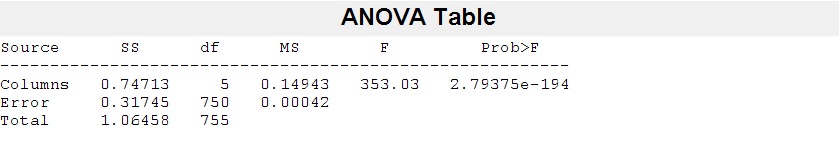

p = 2.7938e-194

tbl = 4×6 cell array
    {'Source' }    {'SS'    }    {'df' }    {'MS'        }    {'F'       }    {'Prob>F'     }
    {'Columns'}    {[0.7471]}    {[  5]}    {[    0.1494]}    {[353.0299]}    {[2.7938e-194]}
    {'Error'  }    {[0.3175]}    {[750]}    {[4.2327e-04]}    {0×0 double}    {0×0 double   }
    {'Total'  }    {[1.0646]}    {[755]}    {0×0 double  }    {0×0 double}    {0×0 double   }


stats = struct with fields:
    gnames: [6×1 char]
         n: [126 126 126 126 126 126]
    source: 'anova1'
     means: [0.1666 0.2280 0.2474 0.2118 0.1850 0.2531]
        df: 750
         s: 0.0206


[p,tbl,stats] = anova1(Mean_values_conditions)

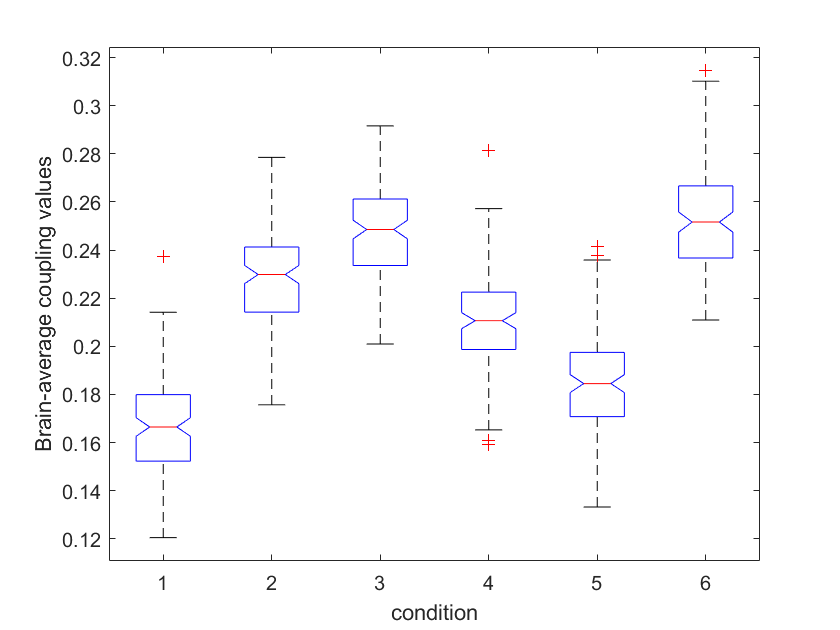

xlabel('condition')
ylabel('Brain-average coupling values')

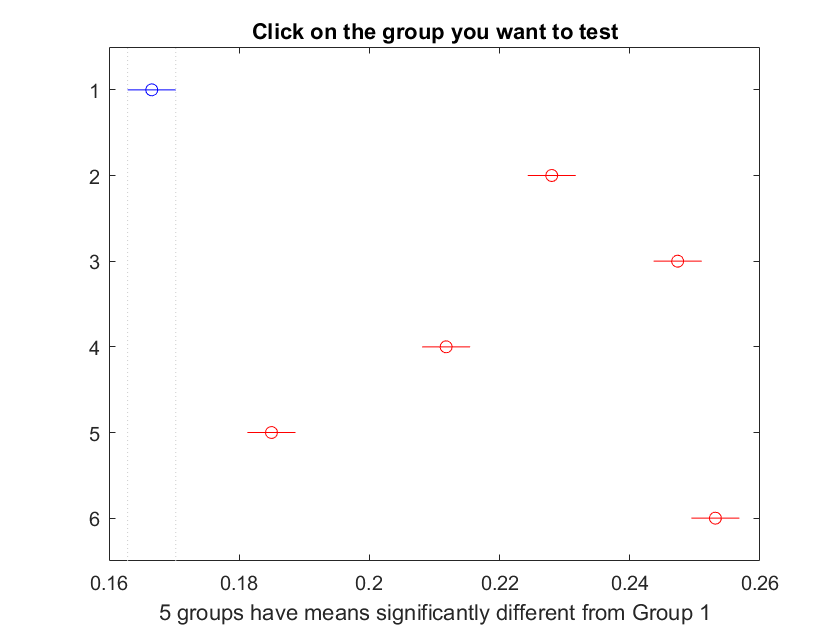

c =     1.0000    2.0000   -0.0688   -0.0614   -0.0541         0
    1.0000    3.0000   -0.0882   -0.0808   -0.0734         0
    1.0000    4.0000   -0.0526   -0.0452   -0.0378         0
    1.0000    5.0000   -0.0258   -0.0184   -0.0110    0.0000
    1.0000    6.0000   -0.0940   -0.0866   -0.0792         0
    2.0000    3.0000   -0.0267   -0.0193   -0.0120    0.0000
    2.0000    4.0000    0.0088    0.0162    0.0236    0.0000
    2.0000    5.0000    0.0357    0.0431    0.0504         0
    2.0000    6.0000   -0.0325   -0.0251   -0.0178    0.0000
    3.0000    4.0000    0.0282    0.0356    0.0430         0


gnames = 6×1 char array
    '1'
    '2'
    '3'
    '4'
    '5'
    '6'


[c,~,~,gnames] = multcompare(stats)

table = array2table(c,"VariableNames",["Group A", "Group B", "Lower Limit", "A-B", "Upper Limit", "P-value"])

table = 15×6 table
    Group A    Group B    Lower Limit       A-B        Upper Limit     P-value  
    _______    _______    ___________    __________    ___________    __________

       1          2        -0.068833      -0.061446      -0.05406              0
       1          3        -0.088174      -0.080787     -0.073401              0
       1          4         -0.05261      -0.045223     -0.037837              0
       1          5        -0.025777      -0.018391     -0.011004     1.5962e-11
       1          6        -0.093969      -0.086583     -0.079196              0
       2          3        -0.026727      -0.019341     -0.011954      9.167e-13
       2          4        0.0088366       0.016223       0.02361     5.5766e-09
       2          5         0.035669       0.04

**5. Run Repeated-measures ANOVA **

data = Mean_values_conditions

data =     0.1585    0.2363    0.2428    0.1987    0.1483    0.2382
    0.1872    0.2317    0.2461    0.1988    0.1946    0.2692
    0.1690    0.2036    0.2436    0.2178    0.1880    0.2544
    0.1862    0.2367    0.2543    0.2301    0.1949    0.2447
    0.1799    0.2503    0.2771    0.2812    0.1968    0.3102
    0.1506    0.2309    0.2332    0.2124    0.1912    0.2281
    0.1818    0.2711    0.2599    0.2261    0.2378    0.2667
    0.1344    0.2072    0.2010    0.1950    0.1631    0.2367
    0.1940    0.2323    0.2692    0.2126    0.2056    0.2807
    0.1467    0.2062    0.2346    0.2120    0.1459    0.2501


subjects = (1:size(data,1))';  % Subject IDs

% Convert to table format
T = array2table(data, 'VariableNames', {'rest','wm','emo-a','emo-m','face', 'gender'});
T.Subjects = subjects;

% Define Table
numbers = [1; 2; 3; 4; 5; 6]

numbers =      1
     2
     3
     4
     5
     6


Infotable = array2table(numbers, 'VariableNames', {'Condition'})

Infotable = 6×1 table
    Condition
    _________

        1    
        2    
        3    
        4    
        5    
        6    



% Define the repeated-measures model
rm = fitrm(T, 'rest-gender ~ 1', 'WithinDesign', Infotable);

% Perform repeated-measures ANOVA
ranovatbl = ranova(rm)

ranovatbl = 2×8 table
                              SumSq     DF       MeanSq        F         pValue        pValueGG       pValueHF       pValueLB 
                             _______    ___    __________    ______    ___________    ___________    ___________    __________

    (Intercept):Condition    0.74713      5       0.14943    631.84    1.2576e-241    7.0296e-219    5.6047e-228    1.0239e-50
    Error(Condition)         0.14781    625    0.00023649                                                                     



% Display results
disp(ranovatbl)

                              SumSq     DF       MeanSq        F         pValue        pValueGG       pValueHF       pValueLB 
                             _______    ___    __________    ______    ___________    ___________    ___________    __________

    (Intercept):Condition    0.74713      5       0.14943    631.84    1.2576e-241    7.0296e-219    5.6047e-228    1.0239e-50
    Error(Condition)         0.14781    625    0.00023649                                                                     



% Perform post-hoc tests
multcompare(rm, 'Condition')

ans = 30×7 table
    Condition_1    Condition_2    Difference     StdErr        pValue        Lower         Upper   
    ___________    ___________    __________    _________    __________    _________    ___________

         1              2          -0.061446    0.0022204    2.0676e-08    -0.067774      -0.055119
         1              3          -0.080787    0.0021593    2.0676e-08     -0.08694      -0.074634
         1              4          -0.045223    0.0021312    2.0676e-08    -0.051297       -0.03915
         1              5          -0.018391    0.0020612    2.0676e-08    -0.024264      -0.012517
         1              6          -0.086583    0.0021005    2.0676e-08    -0.092569      -0.080597
         2              1           0.061446